Question2)

set index:

load('data.mat');
%changing values 
chars={'qt','qh','tr','al','ah','aw'};
y = replace(data,chars,{'1','2','3','4','5','6'});
y = cellfun(@str2double,y(:,1:end-1),'UniformOutput',false);
y=cell2mat(y)

y =      5     5     5     5     5     5     5     5     3     5     3     5     5     2     1     1     1     1     1     3     1     1     1     1     1     1     1     1     1     1     3     4     4     4     4     4     3     5     4     4     4     4     4     5     5     5     5     5     5     5


fourier transform:

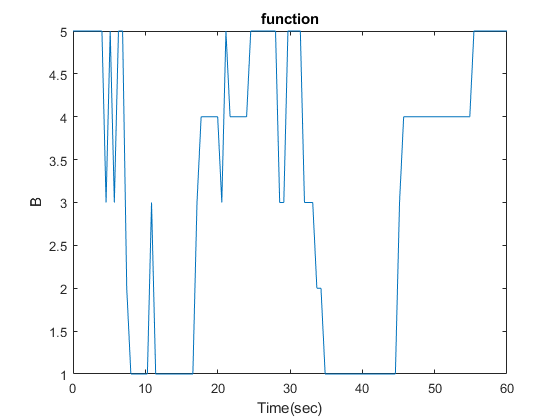

%original function
time_step=0.016666666666666667;
fs=1/time_step;
x = linspace(0,fs,length(y));
%
plot(x,y)
title function
ylabel B
xlabel Time(sec)

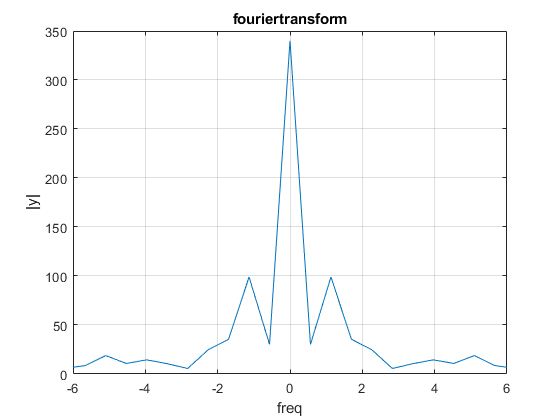

%transform
n= length(y);
fFft=(-n/2:n/2-1)*(fs/n);
yFft=fft(y);
yFftshift=fftshift(yFft);
plot(fFft,abs(yFftshift))
title fouriertransform
xlim([-6,6])
xlabel("freq")
ylabel("|y|")
grid on

frequency spectrum:

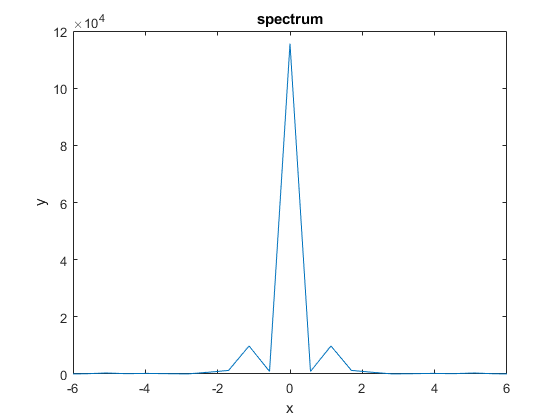

spectrum =abs(yFftshift.^2);
plot(fFft,spectrum);
title('spectrum');
xlim([-6,6])
xlabel("x")
ylabel("y")

every 3 hours cycle repeats

-repeat with diffrent index

%changing values 
y2 = replace(data,chars,{'1','1','2','2','3','3'});
y2 = cellfun(@str2double,y2(:,1:end-1),'UniformOutput',false);
y2=cell2mat(y2)

y2 =      3     3     3     3     3     3     3     3     2     3     2     3     3     1     1     1     1     1     1     2     1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2     3     2     2     2     2     2     3     3     3     3     3     3     3


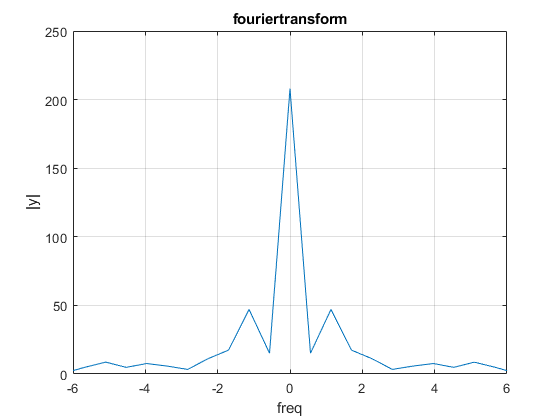

%transform
n= length(y2);
fFft2=(-n/2:n/2-1)*(fs/n);
yFft2=fft(y2);
y2Fftshift=fftshift(yFft2);
plot(fFft2,abs(y2Fftshift))
title fouriertransform
xlim([-6,6])
xlabel("freq")
ylabel("|y|")
grid on

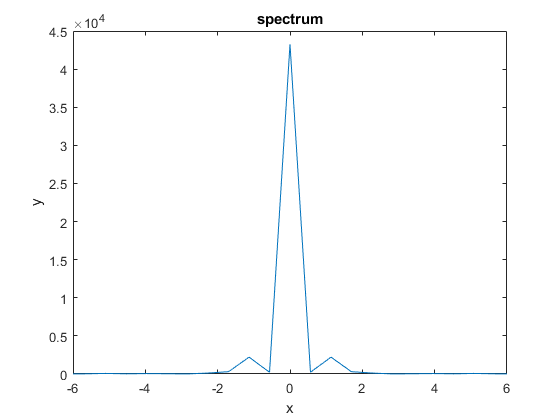

%spectrum
spectrum2 =abs(y2Fftshift.^2);
plot(fFft2,spectrum2);
title('spectrum');
xlim([-6,6])
xlabel("x")
ylabel("y")